# 05 Křížová korelace a autokorelace

Samostatnou technikou pro porovnávání dvojice signálů v časové oblasti je tzv. **křížová korelace** (cross-correlation), též známá jako **korelační funkce**. Křížová korelace $R_{\textrm{xy}} \left(\tau \right)$ reprezentuje "vzájemnou energii" dvojice signálů v závislosti na měnícím se časovém posunu $\tau$ mezi signály, přičemž výpočet nepoužívá absolutní hodnotu. Fyzikální energie musí vždy nabývat kladné hodnoty, zde ale ve výsledku ponecháme znamínko. To je výhodné pro popis **inverzních** signálů, jejichž vzájemná energie je popisována jako **záporná korelace**. Můžeme si to představit na porovnání signálu, který je zesílen invertujícím a neinvertujícím zapojením. Zesílené signály mají obrácenou polaritu, jinak jsou totožné, tedy záporně korelované.

V číslicovém zpracování pracujeme s dikrétními hodnotami, proto nejmenší možný posun $\tau$ mezi signály může být jeden vzorek $m$, rovnice (1) . Časová hodnota posunu $\tau$ je poté spočtena přes vzorkovací kmitočet, rovnice (2).


$$\begin{array}{l}
{\left(1\right)\;\;\;\;\;\;\;\;\;\;R}_{\textrm{xy}} \left\lbrack m\right\rbrack =\sum_{n+1}^N x\left\lbrack n+m\right\rbrack \cdot {y\left\lbrack n\right\rbrack }^* ;m\in \left(-N+1,N-1\right)\\
\left(2\right)\;\;\;\;\;\;\;\;\;\;\tau =\frac{m}{f_s }
\end{array}$$


Křížová korelace se používá zejména pro zjištění časového zpoždění mezi dvěma signály, které nesou podobnou informaci. Velikost korelace je maximální, pokud je časový posun mezi signály vykompenzován. 

Této základní vlastnosti lze využít i při hledání periodicit v signálu nebo např. ozvěn. Křížová korelace je provedena mezi signálem a sebou samým, tj.  **autokorelace **$R_{\textrm{xx}} \left\lbrack m\right\rbrack$; rovnice (3). Hodnota autokorelace pro nulový posun tedy reprezentuje celkovou energii signálu $E_x =R_{\textrm{xx}} \left\lbrack 0\right\rbrack$.

   
$${\left(3\right)\;\;\;\;\;\;\;\;\;\;R}_{\textrm{xx}} \left\lbrack m\right\rbrack =\sum_{n+1}^N x\left\lbrack n+m\right\rbrack \cdot {x\left\lbrack n\right\rbrack }^* ;m\in \left(-N+1,N-1\right)$$


Frekvenčním obrazem autokorelační funkce je výkonová spektrální hustota signálu PSD: ${X\left\lbrack f\right\rbrack \cdot {X\left\lbrack f\right\rbrack }^* =\left|X\left\lbrack f\right\rbrack \right|}^2 =\textrm{DFT}\left\lbrace {\mathbf{R}}_{\textrm{xx}} \right\rbrace$. V případě křížové korelace je její frekveční spektrum vzájemné $X\left\lbrack f\right\rbrack \cdot {Y\left\lbrack f\right\rbrack }^*$ a absolutní hodnota odpovídá vzájemné výkonové hustotě CPSD: $\left|X\left\lbrack f\right\rbrack \cdot {Y\left\lbrack f\right\rbrack }^* \right|=\left|\textrm{DFT}\left\lbrace {\mathbf{R}}_{\textrm{xy}} \right\rbrace \right|$. Vzájemná výkonová hustota (CPSD) reprezentuje vzájemný výkon/energii jednotlivých spektrálních složek dvojice signálů (skalární násobení spekter). To je výhodné při analýze zdánlivě rozdílných signálů, které ale obsahují shodné harmonické či kvaziperiodické složky. V CPSD se tyto složky násobením zvýrazní, a tím poukáží na možnost provázanosti mezi signály, naopak rozdílné složky jsou potlačeny.

Výpočet korelační a autokorelační funkce (pomocí křížové korelace a autokorelace) má dle definice výpočetní náročnost $N^2$. Rychlá implementace `xcorr` využívá faktu, kdy spektrum signálu lze spočítat pomocí FFT v náročnosti $N\;\log \;N$. Výpočet výkonového spektra umocněním je náročnosti $N$ a inverzní transformací IFFT lze získat korelační funkci v náročnosti $N\;\log \;N$. Vztahy mezi signálem, spektrem, výkonovým spektrem a korelační funkcí znázorňuje **DSP čtyřúhelník** (**častá otázka u státní zkoušky**).   

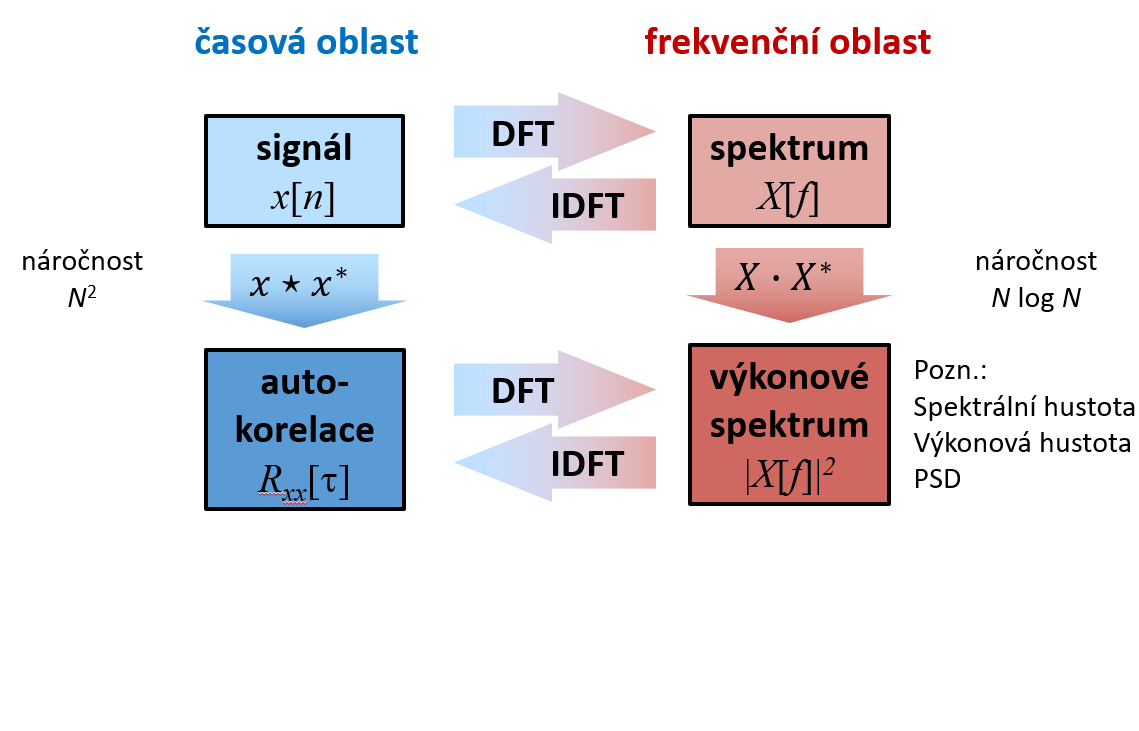      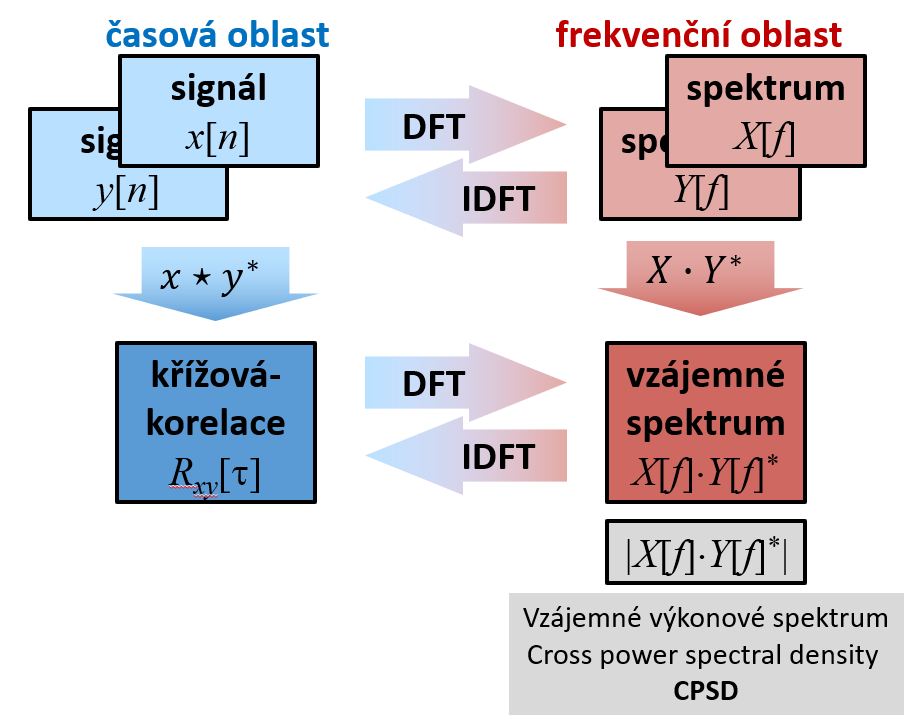

Stanovení maxima v korelační funkci umožňuje určit časové zpoždění signálů, či periodicitu v autokorelční funkci, to nám ovšem nic nevypovídá o **míře podobnosti** dvojice signálů. Pokud ovšem "vzájemnou energii" signálů nanormujeme energiemi jednotlivých signálů, hodnoty korelace poté nabudou hodnot $R\in \left\langle -1;1\right\rangle$, tedy mezi 0 až 100% podobností mezi signály, respektive 0 až -100% antipodobnosti. Takto definovanou křížovou korelaci můžeme nazývat **korelačním koeficientem **křížové korelace nebo autokorelace:


$$\left(4\right)\;\;\;\;\;\;\;\;\;\;\widehat{R_{\textrm{xy}} } \left\lbrack m\right\rbrack =\frac{R_{\textrm{xy}} \left\lbrack m\right\rbrack }{\sqrt{R_{\textrm{xx}} \left\lbrack 0\right\rbrack {\cdot R}_{\textrm{yy}} \left\lbrack 0\right\rbrack }}$$


Pozn.: V signálovém zpracování se často můžete setkat se slangovým označením "**korelace"** jak pro křížovou korelaci (korelační funkci) tak i autokoralaci (autokorelační funkci). To není ovšem přesné, protože obě jmenované jsou funkcí a výstupem je vektor hodnot korelace v závislosti na posunu. **Korelace **$C$, též lineární korelace, korelační koeficient či míra korelace, je statistictickým ukazatelem míry podobnosti dvojice číselných řad **bez posunu**. V kontextu rovnice (4) tedy platí pro posun $m=0$:


$$\left(5\right)\;\;\;\;\;\;\;\;\;\;C=\frac{R_{\textrm{xy}} \left\lbrack 0\right\rbrack }{\sqrt{R_{\textrm{xx}} \left\lbrack 0\right\rbrack {\cdot R}_{\textrm{yy}} \left\lbrack 0\right\rbrack }}$$
    

**Cíle:**

**    1) Křížová korelace**

- Vygenerujte dva navzájem zpožděné signály s obdélníkovými pulzy

- Proveďte křížovou korelaci a změřením ověřte zpoždění

**    2) Křížová korelace a vzájemné výkonové spektrum**

- Načtěte signál z tříosého akcelerometru

- Vizuálně identifikujte kanály (osy) reprezentující cykly chůze

- Z křížové korelační funkce spočtěte vzájemnou spektrální hustotu

- Z dominantního kmitočtu odhadněte počet kroků a ušlou vzdálenost

- Vyzkoušejte i na nekvalitním (zašumněném) záznamu

    **3) Autokorelace**

- Načtěte zvukový záznam „hlášení místního rozhlasu“

- Pomocí autokorelace identifikujte ozvěnu

- Z časového zpoždění mezi přeslechy spočtěte vzdálenost mezi ampliony

    **BONUS:**** Korelační koeficient**

- Z dostupných dat stanovte souvislost mezi počtem infikovaných onemocněním COVID-19 a počtem zemřelých 

- Stanovte korelaci a zpoždění mezi počtem infikovaných a počtem úmrtí s COVID, stanovte celkovou smrtnost

- Stanovte průměrnou úmrtnost v ČR od 2005 do konce 2019 a porovnejte s obdobím 2020-2021. Rozdíl porovnejte s úmrtími pacientů s COVID.  

**Užitečné funkce: **`xcorr, corr, audioread, datetick, datenum, sum, max`

## Nápověda:

### 1) Křížová korelace

Vytvořte dva sekundové signály $x\left\lbrack t_n \right\rbrack$ a $y\left\lbrack t_n \right\rbrack$ obsahující obdélníkový 50ms pulz. Mezi obdélníky vytvořte zpoždění např. 100 ms. Při tvorbě signálů nezapomeňte časové parametry přepočítat na vzorky! Také vytvořte časovou osu signálů.

fs=1000; % vzorkovací kmitočet
T= 1;
N = fs*T;
delta = 100;       % delta=... 100 ms
x=zeros(fs,1); % nulový signál délky fs vzorků, tj. 1 s
x(100/1000*fs:150/1000*fs) = 1;        % x(100 ms až 150 ms) = 1 (50 ms pulz)
 
y=zeros(fs,1); % nulový signál délky fs vzorů, tj. 1 s
y((100+delta)/1000*fs:(150+delta)/1000*fs) = 1;        % y(100 ms + delta až 150 ms + delta) = 1 (zpožděný 50 ms pulz)
t = 0:1/fs:T-1/fs;      % t=... časová osa

**Vypočtěte křížovou korelaci mezi signály **$x\left\lbrack n\right\rbrack$ **a** $y\left\lbrack n\right\rbrack$**:**


$$R_{\textrm{xy}} \left\lbrack m\right\rbrack =\sum_{n+1}^N x\left\lbrack n+m\right\rbrack \cdot {y\left\lbrack n\right\rbrack }^*$$


Uvědomte si, že výstupem funkce `xcorr()` je křížová korelace `r` v závislosti na posunu  mezi signály `lags`, které jsou **ve vzorcích**. Přepočítejte pomocí `fs` hodnoty `lags` na čas `tau`.  

[Rxy,m] = xcorr(x,y);        % [Rxy,m]=xcorr(... křížová korelace
tau = m/fs        % tau=... přepočet posunu m-vzorků na čas

tau =        -0.999       -0.998       -0.997       -0.996       -0.995       -0.994       -0.993       -0.992       -0.991        -0.99       -0.989       -0.988       -0.987       -0.986       -0.985       -0.984       -0.983       -0.982       -0.981        -0.98       -0.979       -0.978       -0.977       -0.976       -0.975       -0.974       -0.973       -0.972       -0.971        -0.97       -0.969       -0.968       -0.967       -0.966       -0.965       -0.964       -0.963       -0.962       -0.961        -0.96       -0.959       -0.958       -0.957       -0.956       -0.955       -0.954       -0.953       -0.952       -0.951        -0.95


Zobrazte signály $x\left\lbrack t_n \right\rbrack ,y\left\lbrack t_n \right\rbrack \;\mathrm{a}\;R_{\textrm{xy}} \left\lbrack \tau \right\rbrack$. 

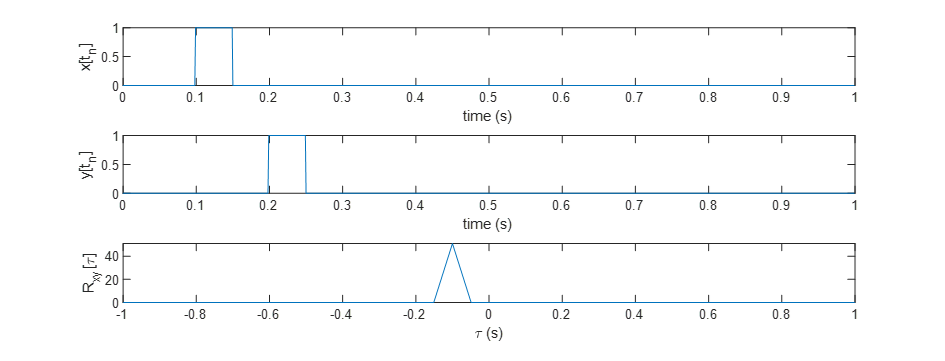

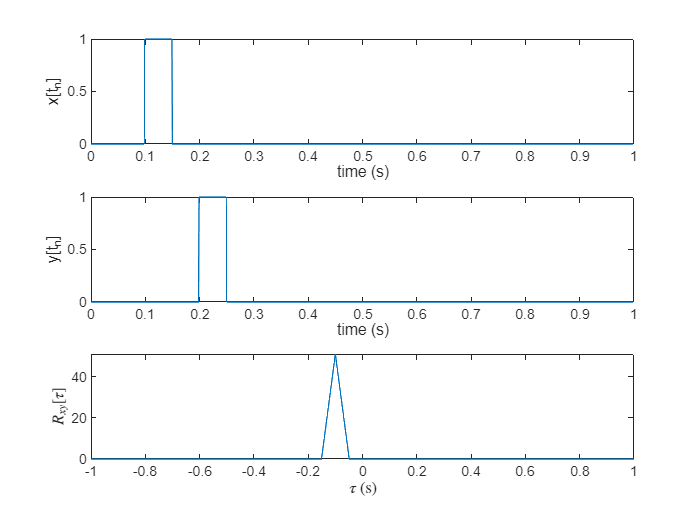

figure
subplot(3,1,1)
plot(t,x)
xlabel("time (s)")
ylabel('x[t_n]')
subplot(3,1,2)
plot(t,y)
xlabel("time (s)")
ylabel('y[t_n]')
subplot(3,1,3)
plot(tau,Rxy)
xlabel('$\tau$ (s)','Interpreter','latex')
ylabel('$R_{xy}[\tau]$','Interpreter','latex')

### **2) Krokoměr (CPSD)**

clear all; close all;

Akcelerometrická měření jsou běžnou součástí nositelné elektroniky, mobilních telefonů nebo systémů sledujících polohu pacienta. Citlivost, SNR, přesnost měření, frekvenční charakteristika, rozsah zrychlení apod. jsou často odvislé od ceny a typu senzoru. Kvalita signálu poté závisí na mnoha faktorech, jako je upevnění seznoru aj. Při chůzi dochází přirozeně k zrychlování (odraz) a zpomalování (došlápnutí). Z kvaziperiodického signálu zrychlení lze vyčíst periodickou sloužku střídání nohou (kroků) a odhadnout vzdálenost chůze a počet kroků. Signál z tříosého akceloremotru poskytuje redundantní informaci o cyklech chůze, protože dominantní složka zrychlení se projevuje jak posterio-anteriorním směru (ve směru chůze - osa z), tak i v superio-inferiorním (kolmém k podložce - osa y), i když se vzájemným časovým zpožděním. Toho půjde využít pro zvýšení citlivosti detekce chůze, kdy společnou frekvenční komponentu obou signálů zvýrazníme a rozdílnou potlačíme. Pravo-levá složka (osa x) ponese informaci o kývání ze strany na stranu vlivem střídání nohou (dva kroky) a bude mít poloviční frekvenci oproti došlápnutí (jeden krok). 

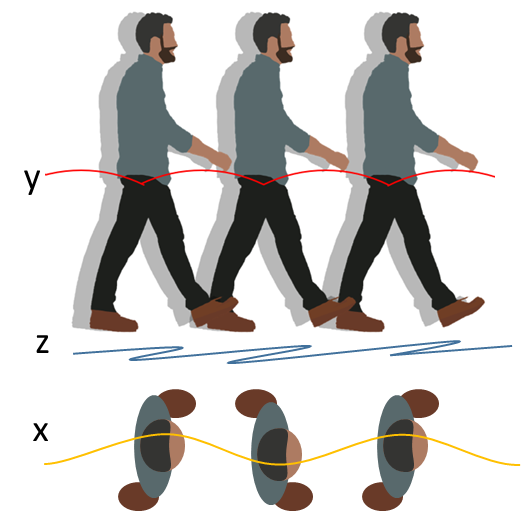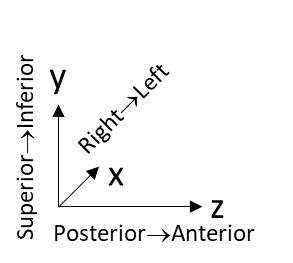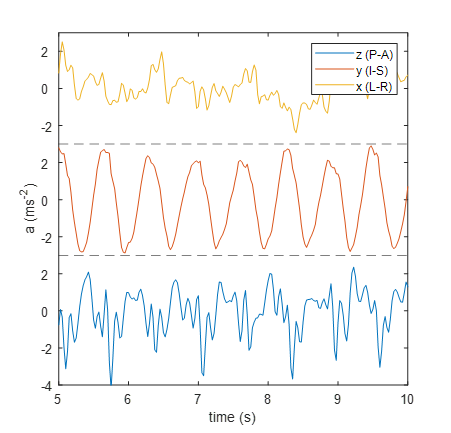

Načtěte si signál z akceleromatru. Ze vzorkovacího kmitočtu vytvořte frekvenční osu.

Zobrazte signály jednotlivých kanálů a jejich absolutní spektra včetně frekvenční osy:

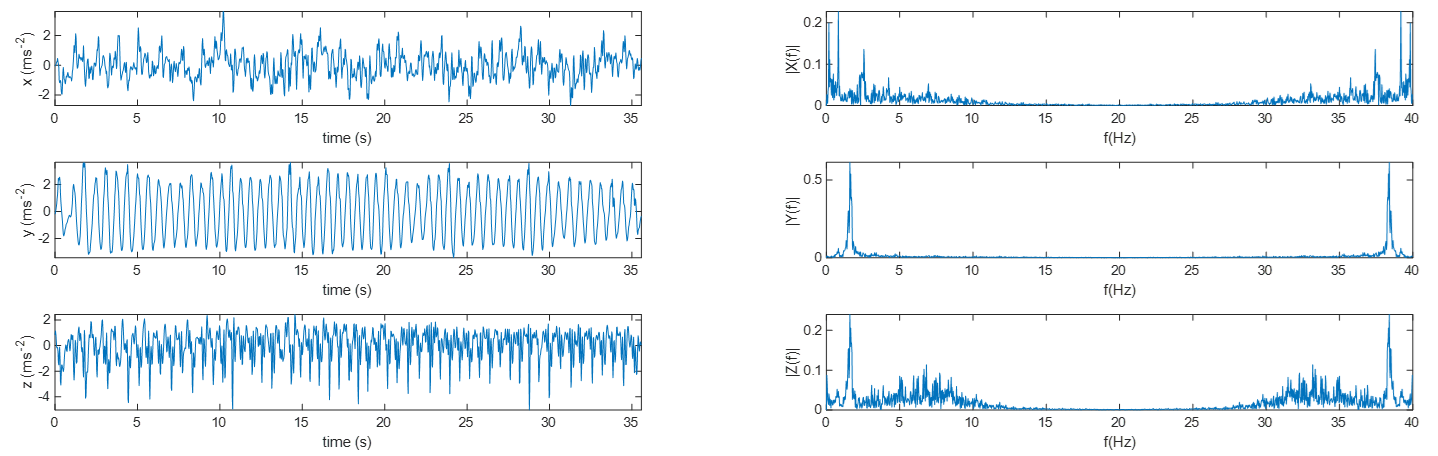t

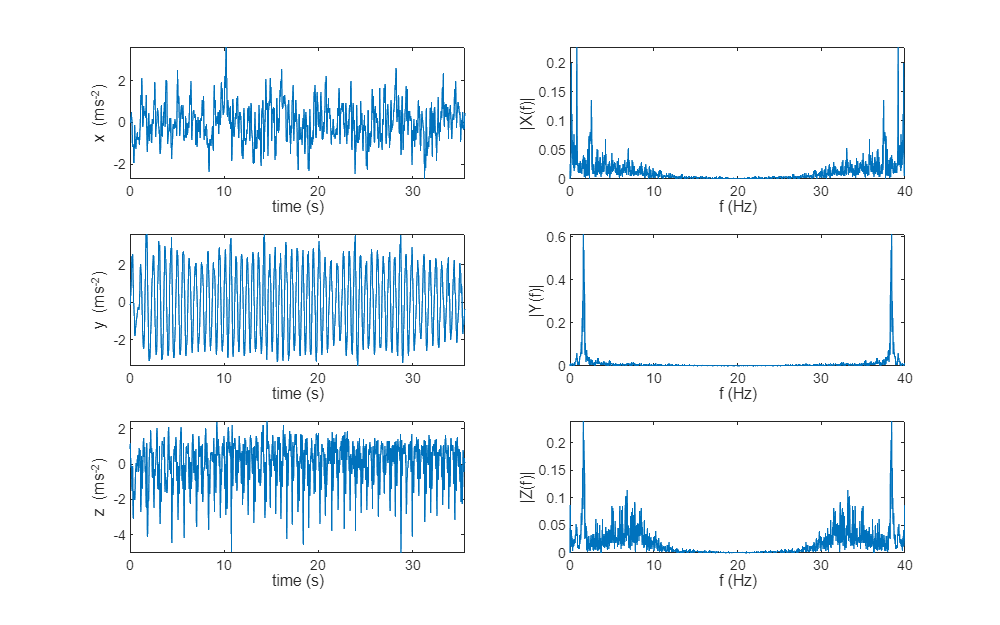

load('accelerometer_walking_quality.mat','x','y','z','fs')
%load('accelerometer_walking_noise.mat','x','y','z','fs') % Pro další iteraci (viz níže)
N = length(x);
T = N/fs;
t = linspace(0,(N/fs-1/fs),N);
f = linspace(0,fs - fs/N,N);

X = 1/N.*fft(x);
Y = 1/N.*fft(y);
Z = 1/N.*fft(z);
figure

set(gcf,'Position',[0 0 800 500])
subplot(3, 2, 1)
plot(t,x')
axis tight
xlabel("time (s)")
ylabel('x (ms^{-2})')

subplot(3,2,2)
plot(f,abs(X))
xlabel("f (Hz)")
ylabel("|X(f)|")

subplot(3, 2, 3)
plot(t,y')
axis tight
xlabel("time (s)")
ylabel('y (ms^{-2})')

subplot(3, 2, 4)
plot(f,abs(Y))
xlabel("f (Hz)")
ylabel("|Y(f)|")

subplot(3, 2, 5)
plot(t,z')
axis tight
xlabel("time (s)")
ylabel('z (ms^{-2})')
subplot(3,2,6)
plot(f,abs(Z))
xlabel("f (Hz)")
ylabel("|Z(f)|")

**Odpovězte:**

**Ve kterém kanále (ose) lze nejlépe identifikovat frekvenci kroků? v kanále y**

Pomocí funkce `[max_val, idx_max]=max()` nalezněte ve spektru vybraného kanálu dominantní frekvenci, tj. frekvenci s největší hodnotou amplitudy.

[max_val, idx_max] = max(abs(Y));
f0=f(idx_max); % F-frekvenční osa; idx_max-index maxima
disp(['Frekvence kroků je: ' num2str(f0) ' Hz'])

Frekvence kroků je: 1.6011 Hz


**Spočtěte, jakou vzdálenost ušel (m) a jakou průměrnou rychlostí (km/h) ušel proband o výšce 183 cm za čas snímání. Předpokládejte, že délka kroku je 41% výšky.**

steps = f0*T;
step_len=183*0.41*1e-2;
dist = step_len * steps;
speed = dist/T;
disp(['Proband za čas snímání ušel ' num2str(dist) ' m rychlostí ' num2str(speed*3.6) ' km/h'])

Proband za čas snímání ušel 42.7671 m rychlostí 4.3248 km/h


Spočítejte křížovou korelaci $R_{\textrm{xy}} \left\lbrack \tau \;\right\rbrack$ dvojicí kanálů nejlépe snímající chůzi (osy y a z) a spočtěte vzájemnou výkonou hostutu ${\textrm{CPSD}}_{\textrm{xy}} \left\lbrack f\right\rbrack =\left|\textrm{DFT}\left\lbrace R_{\textrm{xy}} \right\rbrace \right|$. Určete dominantní frekvenci chůze.

Dvojici signálů, jejich křížovou korelacní funkci, magnitudová spektra a vzájemné výkonové spektrum zobrazte v DSP čtyřúhleníku.

**Pozn.:** U korelace spočítejte uveďte osu posunu v sekundách. U CPSD nezapomeňte správně definovat frekvenční osu, která oproti spektru signálu bude mít $2N-1$ spektrálních čar.

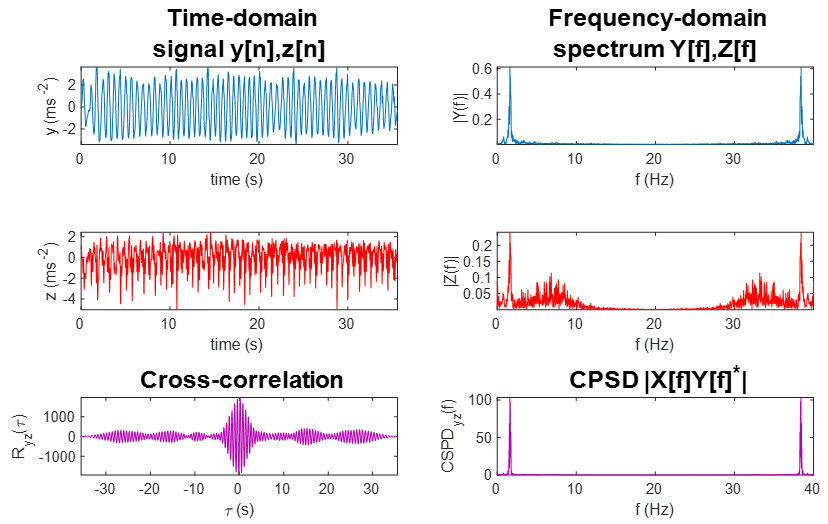

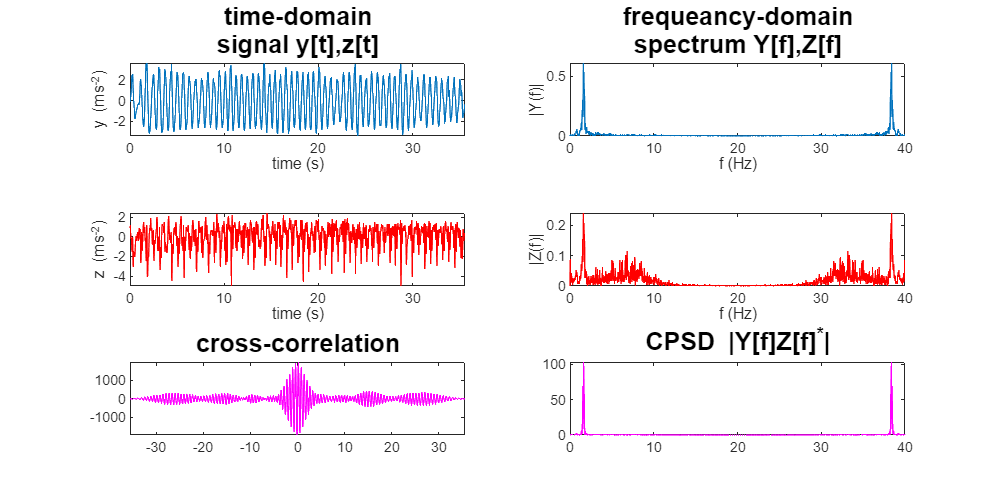

[Ryz,m] = xcorr(y,z);      
tau = m/fs;
N = length(Ryz);
F = linspace(0,fs - fs/N,N);

CPSD = abs(1/N*fft(Ryz));
figure
set(gcf,'Position', [0 0 800 400])
subplot(3, 2, 1)
plot(t,y')
axis tight
xlabel("time (s)")
ylabel('y (ms^{-2})')
title(sprintf('time-domain\nsignal y[t],z[t]'),"FontSize",15,"FontWeight","bold")

subplot(3, 2, 2)
plot(f,abs(Y))
xlabel("f (Hz)")
ylabel("|Y(f)|")
title(sprintf('frequeancy-domain\nspectrum Y[f],Z[f]'),"FontSize",15,"FontWeight","bold")

subplot(3, 2, 3)
plot(t,z',Color='r')
axis tight
xlabel("time (s)")
ylabel('z (ms^{-2})')

subplot(3,2,4)
plot(f,abs(Z),Color='r')
xlabel("f (Hz)")
ylabel("|Z(f)|")
subplot(3,2,5)
plot(tau,Ryz,Color='m')
axis tight
title("cross-correlation","FontSize",15,"FontWeight","bold")
subplot(3,2,6)
plot(F,CPSD,Color='m')
title("CPSD |Y[f]Z[f]^*|","FontSize",15,"FontWeight","bold")

**Celý postup znovu vyzkoušejte na nekvalitně nasnímaném signálu (špatně připevněný senzor):**

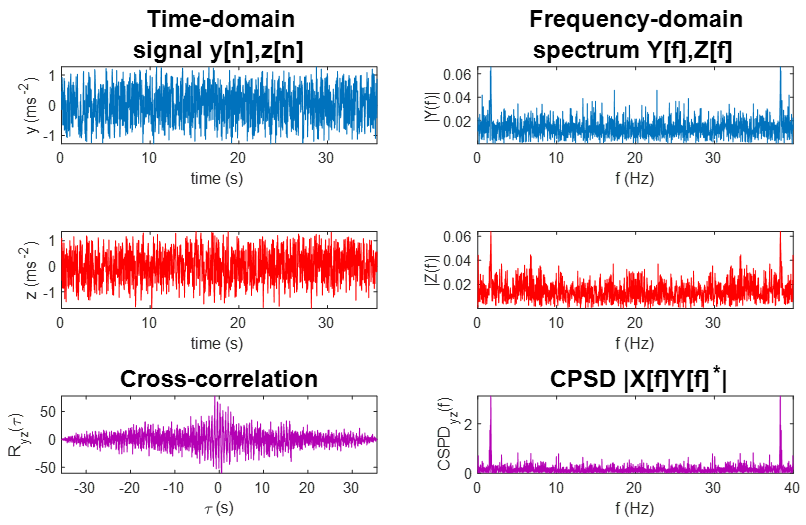

**Zhodnoťte schopnost identifikovat dominantní frekvenci (chůze) oproti spektrálním čarám pozadí (šumu) pomocí CPSD a PSD.**

CPSD zvýrazní společnou dominantní frekvenci (chůzi) obou signálů oproti spektrálním čarám šumu.

### **3) Autokorelace**

Načtěte a poslechněte si záznam hlášením místního rozhlasu `'Rozhlas_echo.m4a'`. Pomocí autokorelační funkce zjistěte čas mezi přeslechy (ozvěnami) způsobenými doputováním zvuku ze vzdálenějšího druhého amplionu. Z časového zpoždění ozvěny a přibližné rychlosti šíření zvuku ve vzduchu 340 m/s odhadněte vzdálenost k druhému amplionu.

[s,fs]=audioread('Rozhlas_echo.m4a');
N = length(s);
T = 1/fs*N;
sound(s,fs)


Zobrazte signál, spočtěte autokorelační funkci, změřte čas do ozvěny a spočtěte dráhu, jakou zvuk za tento čas urazí:

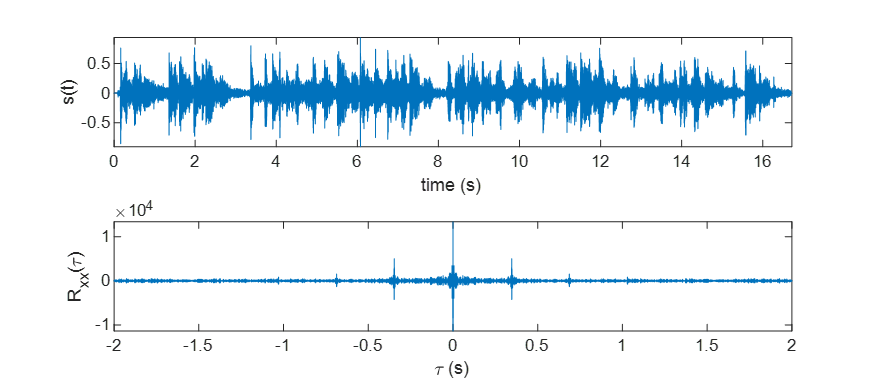

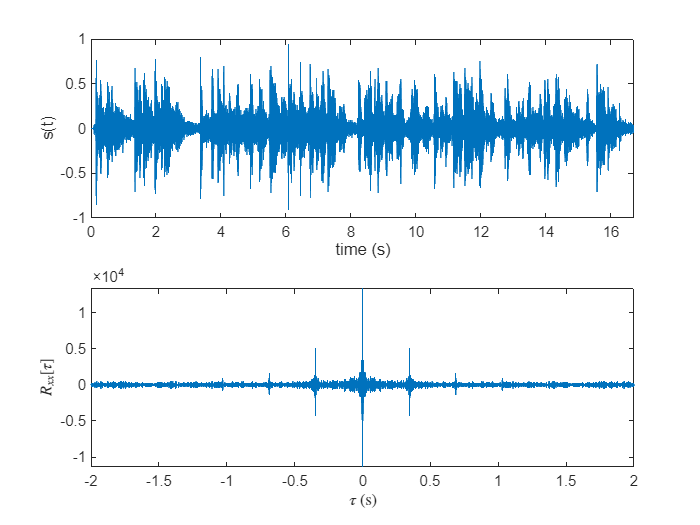

t = linspace(0,T - 1/fs,N);
[Rauto,m] = xcorr(s,s);      
tau = m/fs;

figure
subplot(2,1,1)
plot(t,s)
xlim([0 t(end)])
xlabel("time (s)")
ylabel("s(t)")

subplot(2,1,2)
plot(tau,Rauto)
xlim([-2 2])
xlabel('$\tau$ (s)','Interpreter','latex')
ylabel('$R_{xx}[\tau]$','Interpreter','latex')

idx = (tau>0.2 & tau <0.4);
echo = tau(Rauto == max(Rauto(idx)));
echo = echo(end);
disp(echo)

      0.34658



disp(340*echo)

       117.84



**Doplňte:**

**První ozvěna dorazí s 0,35 sekundovým zpožděním.**

**Vzdálenost druhého amplionu je asi 117,8 metrů.**

### **BONUS: Korelační koeficient jako míra podobnosti signálů**

Pokuste se potvrdit, zda počet pozitivně testovaných na COVID-19 souvisí s počtem zemřelých s COVID-19 a celkovým počtem nadúmrtí v ČR.

clear all; close all;

Načtěte denní statistiku o výskytu infekce COVID-19 (počet pozitivních testů, počet zemřelých s COVID-19) v ČR společně s týdenním reportem úmrtí v ČR mezi lety 2005-2021 `'COVID_data.mat'`. Informace o počtu infikovaných a zemřelých s COVID je v jednodenním rozlišení $f_s =1\;\textrm{den}$ a bylo klouzavě vyhlazeno k odstranění víkendových výkyvů v testování. Statistika zemřelých je uváděna v kalendářních týdnech (`week_death_2005_2021`). Počet zemřelých byl dodatečně přepočítán do týdenního rozlišení (`week_death_covid`). Význam jednotlivých sloupců matic je uložen v cell (`*_label`). První sloupec matic obsahuje datum v `datenum` formátu.

load('COVID_data.mat');
% day_stat... matice denních statistik
% popis sloupců (dle day_stat_label):
%    1      2           3           4       5            6           7
% datum|pozit.(M+Ž)|pozit.(M)|pozit.(Ž)|zemřelí(M+Ž)|zemřelí(M)|zemřelé(Ž) 

% Pozn.: Rozdělte matici do vektorů jednotlivých proměnných, název vektoru vhodně zvolte.
date = day_stat(:,1);
infected = day_stat(:,2);
infected_male = day_stat(:,3);
infected_female = day_stat(:,4);
deaths = day_stat(:,5);
deaths_male = day_stat(:,6);
deaths_female = day_stat(:,7);

Z `day_stat` vykreslete počet infikovaných (pozitivních) v závislosti na čase. Vykreslete zvlášť pro ženy, muže a všechny dohromady:

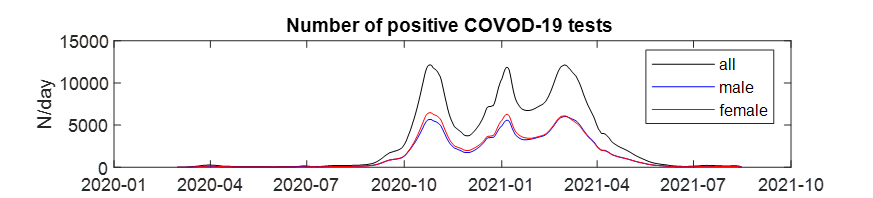

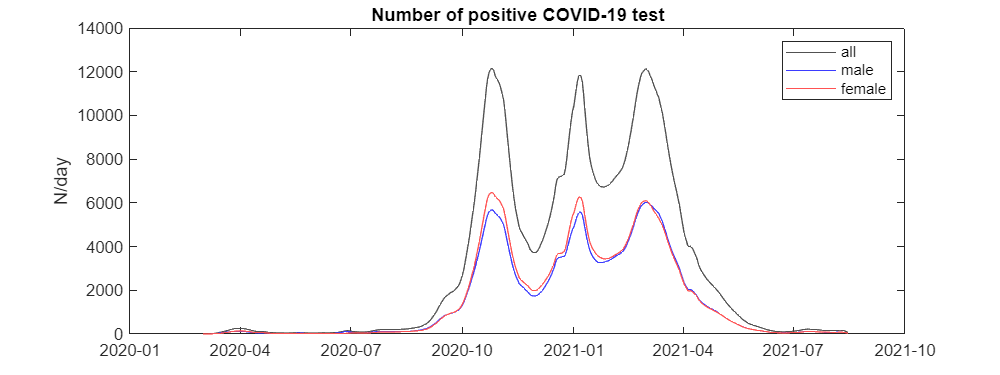

figure 
set(gcf,'Position',[0 0 800 300])

hold on
plot(date,infected,Color='#515151')
plot(date,infected_male, Color='#3b3bff')
plot(date,infected_female,Color='#ff5252')
hold off

datetick('x','yyyy-mm')
legend('all','male','female')
title("Number of positive COVID-19 test")
box on
ylabel("N/day")

To samé proveďte i pro počet zemřelých:

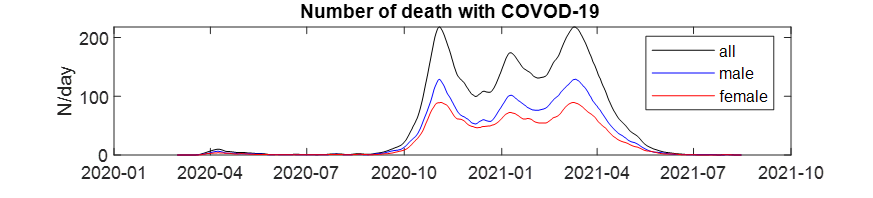

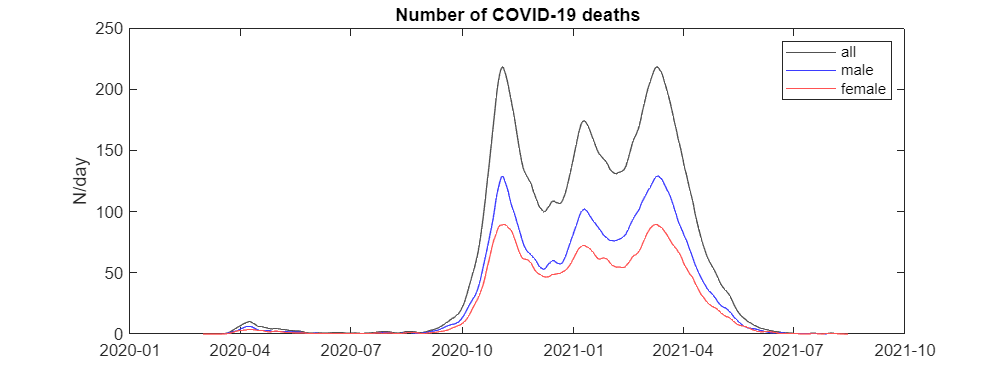

figure 
set(gcf,'Position',[0 0 800 300])

hold on
plot(date,deaths,Color='#515151')
plot(date,deaths_male, Color='#3b3bff')
plot(date,deaths_female,Color='#ff5252')
hold off

datetick('x','yyyy-mm')
legend('all','male','female')
title("Number of COVID-19 deaths")
box on
ylabel("N/day")

Již teď si může povšimnout, že křivky jsou si na první pohled podobné a muži umírali častěji než ženy. Spočtěte normovanou křížovou korelaci (korelačním koeficientem) mezi celkovým počtem pozitivně testovaných a zemřelými (all). Zjistěte, jaké je zpoždění $\tau \;$od infekce k úmrtí a jak jsou si křivky podobné $R_{\textrm{xy}} \left(\tau \right)$:

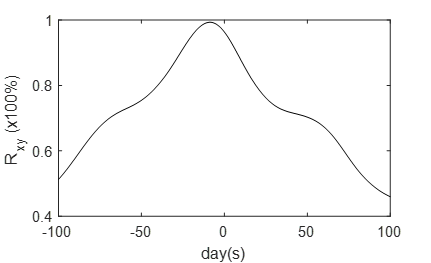

**Proveďte křížovou korelaci nalezněte pozici a hodnotu maxima **`[Rmax,idx]=max()`**. **

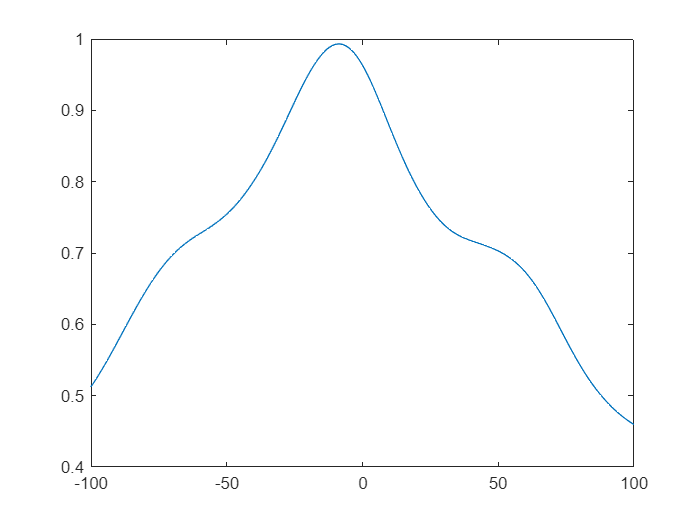

[Rxy,m]=xcorr(infected,deaths,'coef');
tau = m/1;
figure
plot(tau,Rxy)
xlim([-100 100])
ylim([0.4 1])


[Rmax,idx]=max(Rxy);
tau(idx);

disp(['V průměru pacienti s COVID-19 zemřeli ' num2str(abs(tau(idx))) ' dnů od infekce.'])

V průměru pacienti s COVID-19 zemřeli 9 dnů od infekce.


disp(['Počet infenkcí a úmrtí s polu koreluje na ' num2str(Rmax *100) '%'])

Počet infenkcí a úmrtí s polu koreluje na 99.3103%


**Výsledek vypište v **`disp():`

`V průměru pacienti s COVID-19 zemřeli 9 dnů od infekce.`

`Počet infenkcí a úmrtí s polu koreluje na  99.3103 %``.  `

**Stanovte průměrnou smrtnost COVID-19 (počet zemřelých vs. nakažených):**

Z logiky věci v období, kde bylo více případů, je vypočtený poměr více relevantní, nežli v případě záchytů a úmrtí jednotek pacientů. Mohli bychom použít výpočet průměrné hodnoty `mean(R)`, zvolíme ale vhodnější vážený průměr, kde váha reprezentuje počet pozitivně testovaných:


$$\bar{R} =\frac{\sum_i N\left(i\right)R\left(i\right)}{\sum_i N\left(i\right)}$$


R = deaths./infected;
R(isinf(R))  = NaN;
Ravg = (sum(infected.*R,'omitnan'))./sum(infected,"omitnan")

Ravg =      0.018349



R = deaths_male./infected_male;
R(isinf(R))  = NaN;
Ravg = (sum(infected_male.*R,'omitnan'))./sum(infected_male,"omitnan")

Ravg =      0.021683


R = deaths_female./infected_female;
R(isinf(R))  = NaN;
Ravg = (sum(infected_female.*R,'omitnan'))./sum(infected_female,"omitnan")

Ravg =      0.015187


Průměrná smrtnost u člověka je  1,83 %.

Průměrná smrtnost u mužů je 2,17 %.

Průměrná smrtnost u žen je 1,52 %.

**Porovnejte počet zemřelých s COVID-19 a celkový počet nadúmrtí ve stejném období. **

Protože statistika všech úmrtí v ČR je vydávaná jednou za týden (`week_death_2005_2021`), byla denní statistika počtů zemřelých s COVID-19 také přepočtena na týdenní (`week_death_COVID`).

Do jednoho grafu zobrazte celkové počty úmrtí a počet úmrtí s COVID-19:

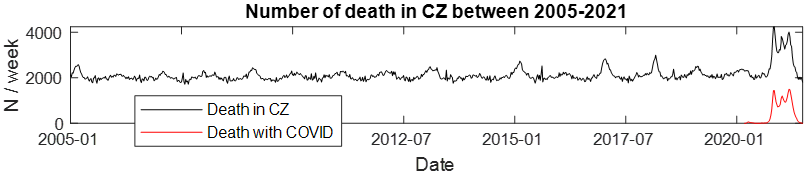

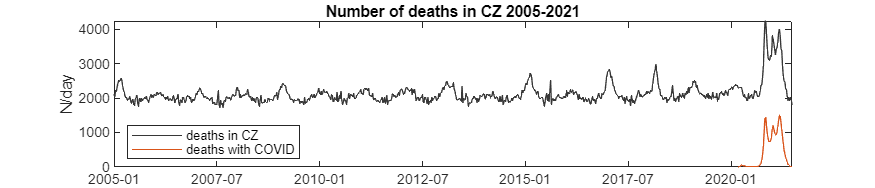

date = week_death_2005_2021(:,1);
deaths = week_death_2005_2021(:,2);

date_covid = week_death_COVID(:,1);
deaths_covid = week_death_COVID(:,2);

figure 

set(gcf,'Position', [0 0 700 150])
hold on
plot(date,deaths,Color='#373737')
plot(date_covid,deaths_covid)
hold off
datetick('x','yyyy-mm')
axis tight
box on
ylabel("N/day")
title("Number of deaths in CZ 2005-2021")
legend('deaths in CZ','deaths with COVID',Location='southwest')

Spočtěte, jaká byla průměrná úmrtnost v ČR před příchodem pandemie:

idx = date<date_covid(1);
deaths_avg = mean(deaths(idx))

deaths_avg =        2075.2


**Průměrná úmrtnost před pandemií byla 2075.2 lidí za týden.**

Vyberte celkový počet úmrtí a úmrtí na COVID-19 jen pro období pandemie. Vyznačte do grafu i průměrnou úmrtnost spočtenou před pandemíí:

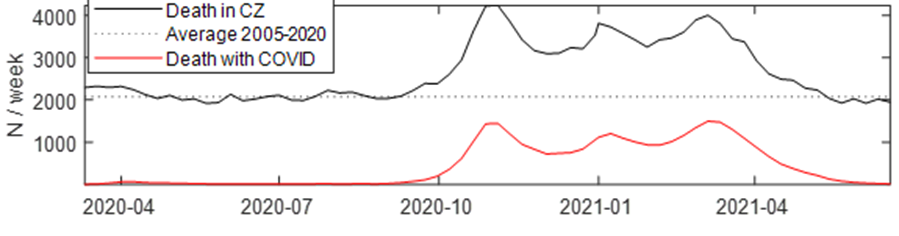

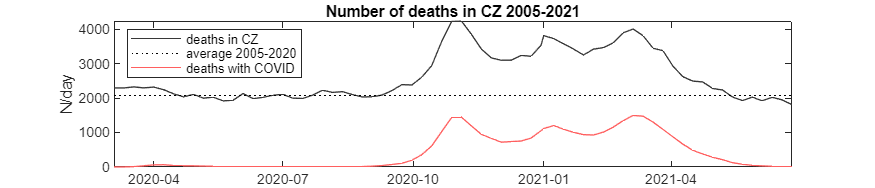

idx = date>=date_covid(1);

figure 
set(gcf,'Position', [0 0 700 150])

hold on
plot(date(idx),deaths(idx),Color='#373737')
plot([date_covid(1) date_covid(end)],[deaths_avg deaths_avg],'k:')
plot(date_covid,deaths_covid,Color='#ff5f5f')
hold off

datetick('x','yyyy-mm')
axis tight
box on
ylabel("N/day")
title("Number of deaths in CZ 2005-2021")
legend('deaths in CZ','average 2005-2020','deaths with COVID',Location='northwest')

Spočtěte korelační koeficient bez posunu $R_{\textrm{xy}} \left\lbrack 0\right\rbrack$ mezi celkovými úmrtími a úmrtími na COVID-19 **v období pandemie**: 

Cxy = corr(deaths(idx),deaths_covid)

Cxy =       0.97865


Spočtěte celkový počet (sumu) nadúmrtí během pandemie, tj. počet úmrtí minus průměrná úmrtnost před pandemií. Spočtěte také celkový počet zemřelých s COVID-19. 

format short g
excess_deaths = sum(deaths(idx)-deaths_avg)

excess_deaths =         40788


sum_death_covid = sum(deaths_covid)

sum_death_covid =         31127


**Doplňte:**

**Celkový počet zemřelých s potvrzeným COVID-19 ve sledovaném obdomí bylo 31127 osob,**

**ale celkový počet nadůmrtí bylo 40788 osob, přičemž vývoj zemřelých na sebe koreluje na  97,86%.**

**Pokuste se vysvětlit rozdíl: **  Může se jednat o neodhalené infekce COVID-19 nebo o úmrtí nepřímo spojená s infekcí (zahlcení nemocnic, odloučení od společnosti apod.). Další možností je příčina nesouvisející s pandemií COVID-19, která ale probíhala současně (stejně jako u pandemie, by muselo jít o jev, který se neděje pravidelně)